Plot original Runge's function

xx = linspace(0, 1)

xx =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


yr = 1 ./ (1 + 25 * xx .^ 2)

yr =     1.0000    0.9975    0.9899    0.9776    0.9608    0.9401    0.9159    0.8889    0.8597    0.8288    0.7968    0.7642    0.7314    0.6988    0.6667    0.6354    0.6050    0.5756    0.5475    0.5206    0.4950    0.4706    0.4475    0.4256    0.4050    0.3855    0.3671    0.3497    0.3334    0.3179    0.3034    0.2897    0.2769    0.2647    0.2532    0.2424    0.2322    0.2226    0.2135    0.2049    0.1968    0.1891    0.1818    0.1749    0.1684    0.1622    0.1563    0.1507    0.1454    0.1404



figure
plot(xx, yr, '--', 'Color','black', 'LineWidth', 2)
hold on
axis([0 1 -1 2])
title('Half Runge function')

xtest = 0.6

xtest = 0.6000

ytrue = 1 ./ (1 + 25 * xtest .^ 2)

ytrue = 0.1000

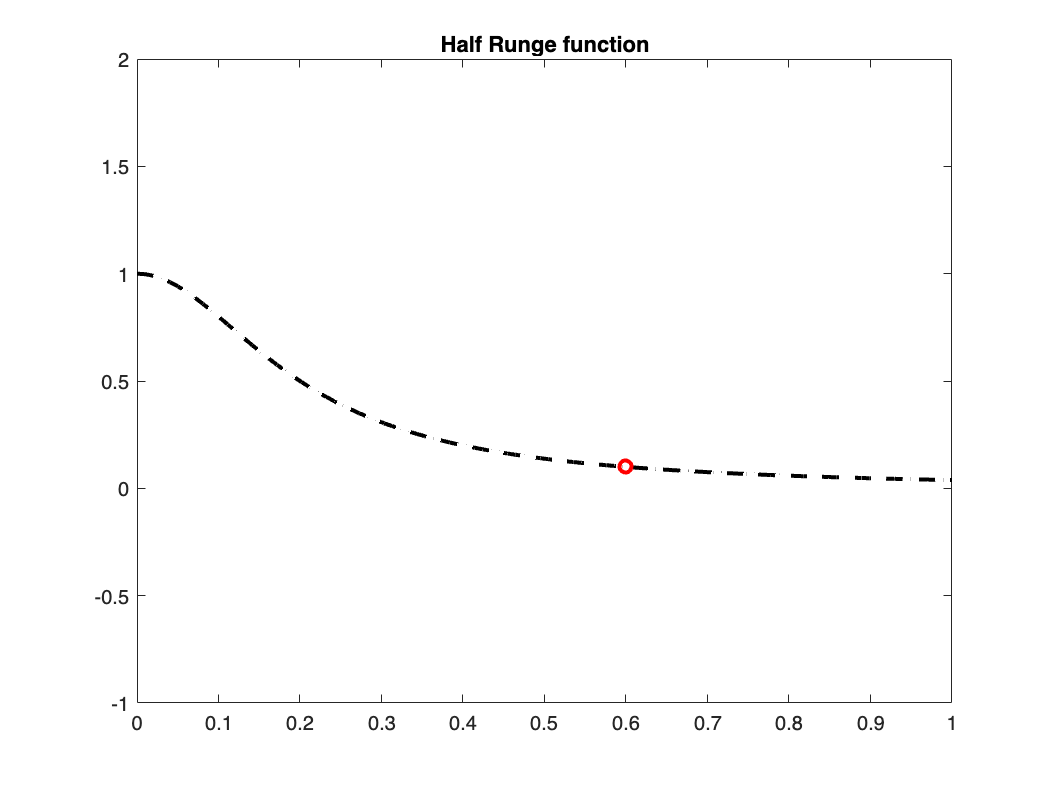


plot(xtest, ytrue, 'rO', 'LineWidth', 2)

Fit with 2th-order polynomial

x = linspace(0, 1 ,3);
y = 1 ./ (1 + 25 * x .^ 2) ;

p2 = polyfit(x, y, 2);
y2 = polyval(p2, xx);

figure
plot(xx, yr, '--', 'Color','black', 'LineWidth', 2)
hold on
plot(x, y, 'O', 'Color','g', 'LineWidth', 2)
hold on
plot(xx, y2, 'Color','r', 'LineWidth', 2)
axis([0 1 -1 2])
title('Runge function and 2-nd order polynomial')

xtest = 0.6

xtest = 0.6000

ypred = polyval(p2, xtest)

ypred = 0.0570

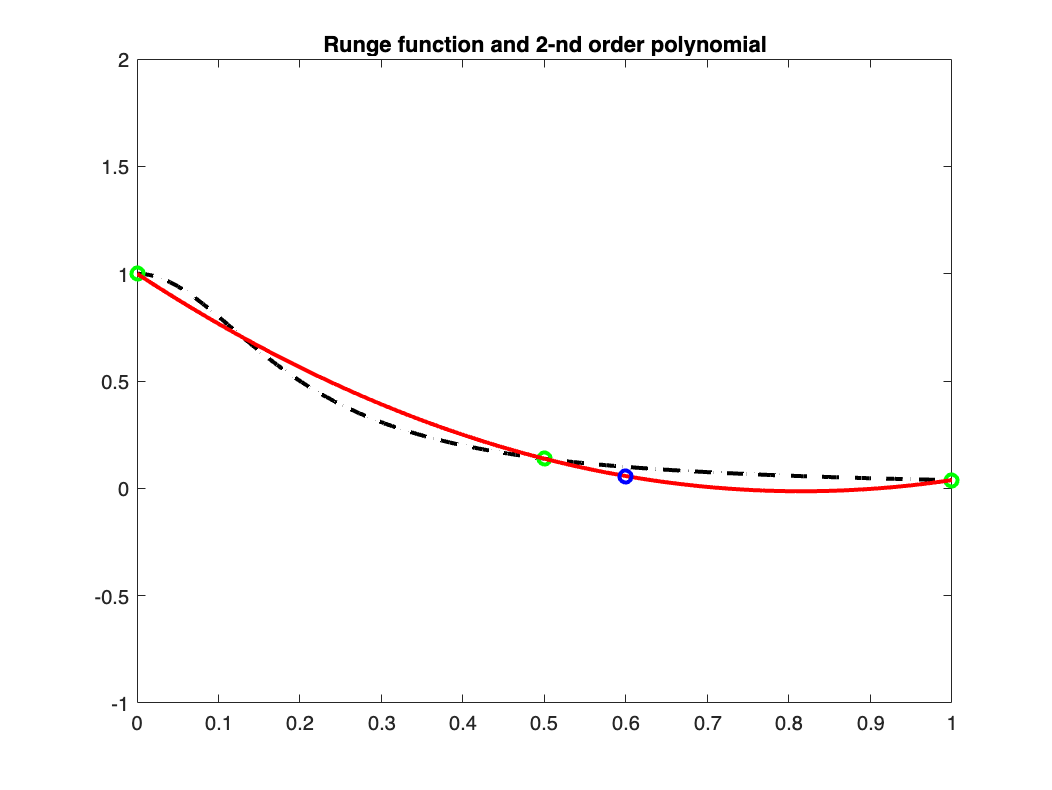

plot(xtest, ypred, 'bO', 'LineWidth', 2)


relative_error2 = abs(((ytrue - ypred) / ytrue) * 100)

relative_error2 = 42.9708

Fit with 3th-order polynomial

x = linspace(0, 1 ,4);
y = 1 ./ (1 + 25 * x .^ 2) ;

p3 = polyfit(x, y, 3);
y3 = polyval(p3, xx);

figure
plot(xx, yr, '--', 'Color','black', 'LineWidth', 2)
hold on
plot(x, y, 'O', 'Color','g', 'LineWidth', 2)
hold on
plot(xx, y3, 'Color','r', 'LineWidth', 2)
axis([0 1 -1 2])
title('Runge function and 3-rd order polynomial')

xtest = 0.6

xtest = 0.6000

ypred = polyval(p3, xtest)

ypred = 0.0947

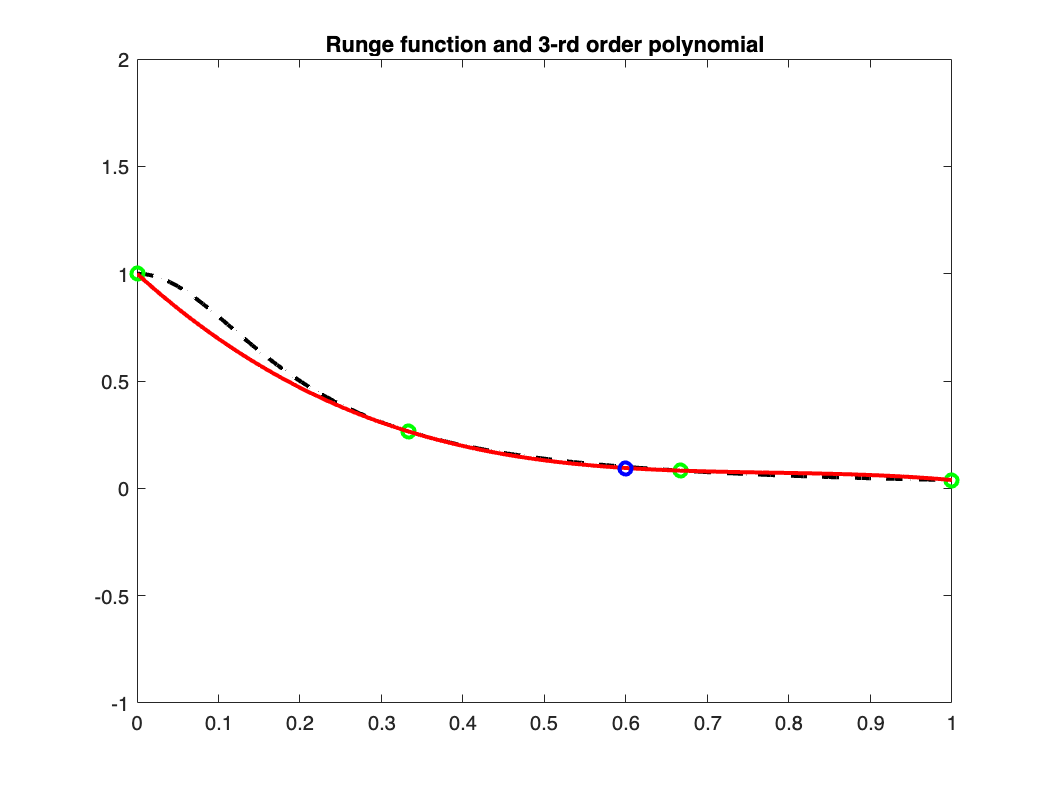

plot(xtest, ypred, 'bO', 'LineWidth', 2)


relative_error3 = abs(((ytrue - ypred) / ytrue) * 100)

relative_error3 = 5.3302

Fit with 4th-order polynomial

x = linspace(0, 1 ,5);
y = 1 ./ (1 + 25 * x .^ 2) ;

p4 = polyfit(x, y, 4);
y4 = polyval(p4, xx);

figure
plot(xx, yr, '--', 'Color','black', 'LineWidth', 2)
hold on
plot(x, y, 'O', 'Color','g', 'LineWidth', 2)
hold on
plot(xx, y4, 'Color','r', 'LineWidth', 2)
axis([0 1 -1 2])
title('Runge function and 4-rd order polynomial')

xtest = 0.6

xtest = 0.6000

ypred = polyval(p4, xtest)

ypred = 0.0962

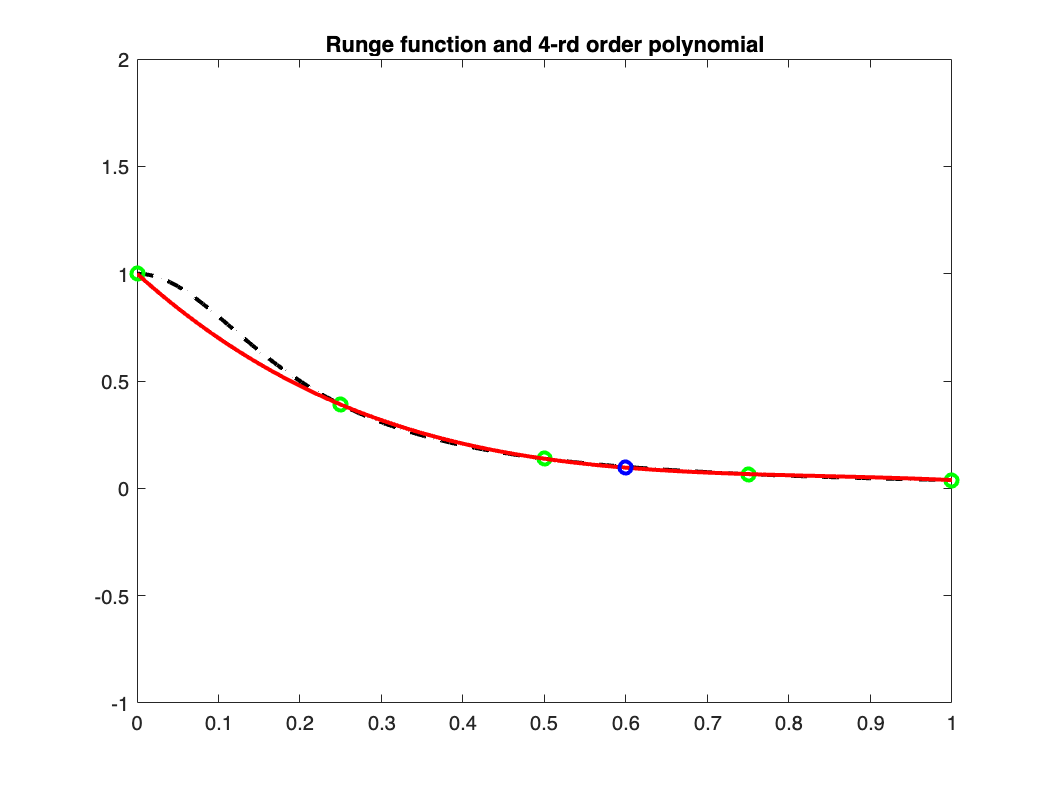

plot(xtest, ypred, 'bO', 'LineWidth', 2)


relative_error4 = abs(((ytrue - ypred) / ytrue) * 100)

relative_error4 = 3.8120

Assume that we have 5 data points from this Runge's function at x = 0.00,  0.25,  0.50,  0.75,  1.00

When y = 0.5, find the correct value of x analytically

ytest = 0.5

ytest = 0.5000

xtrue = sqrt((1/25)*(1/ytest-1))

xtrue = 0.2000

Now assume that we don't know the Runge's function.  Using quadratic interpolation and the quadratic formula to determine the value of x numerically. (use the first three points to fit quadratic polynomial)

x = [0 0.25 0.50];
y = 1 ./ (1 + 25 * x .^ 2);

ytest = 0.5

ytest = 0.5000

p2 = polyfit(x,y,2)

p2 =     2.8595   -3.1539    1.0000



a = p2(1);
b = p2(2);
c = p2(3) - ytest;

[x1, x2] = roots_quadratic_equation(a, b, c)

x1 = 0.9110

x2 = 0.1919

function [x1, x2] = roots_quadratic_equation(a, b, c)
x1 = (-b + sqrt(b^2 - (4 * a * c))) / (2*a);
x2 = (-b - sqrt(b^2 - (4 * a * c))) / (2*a);
end